## TOPIC 14: Data types in MATLAB

ENGR105, 10/20/20

#### Practice problem: Legendre polynomials and recursion

Legendre’s differential equation, depicted below, is seen in many engineering topics including mechanics, fluid dynamics, thermodynamics, and electromagnetism.

        
$$\left(1-x^2 \right)\frac{d^2 }{\mathrm{d}x^2 }y-2x\;\frac{d}{\mathrm{d}x}y+n\left(n+1\right)y=0\;$$


A differential equation of this form is convenient, because solutions can be given as **Legendre polynomials**. The general recurrence formula for the Legendre polynomial may be mathematically represented as the following.

        
$$P_n \left(x\right)=\frac{1}{n}\left\lbrack \left(2n-1\right)x\;P_{n-1} \left(x\right)-\left(n-1\right)\;P_{n-2} \left(x\right)\right\rbrack$$


The first two Legendre polynomials are defined as $P_0 \left(x\right)\;=1$ and $P_1 \left(x\right)=x$.

**a)** **Create a recursive function** named `legendreP` that takes **two inputs**: 1) a vector containing positions at which to evaluate the legendre polynomial, and 2) `n`, a scalar (positive) integer specifying the degree of the Legendre polynomial, as defined in the above equation, to be determined. Your function should have **one output**: `pn`, a vector containing the specified Legendre polynomial. This function should be clear and stored in the space provided at the end of this LiveScript document.

**b)** *Using your function*, produce one plot that contains $P_0 \left(x\right)$, $P_1 \left(x\right)$, $P_2 \left(x\right)$, $P_3 \left(x\right)$, $P_4 \left(x\right)$ plotted over the domain $x\in \left\lbrack 0,1\right\rbrack$. As always, ensure that your plot is professional and clear.

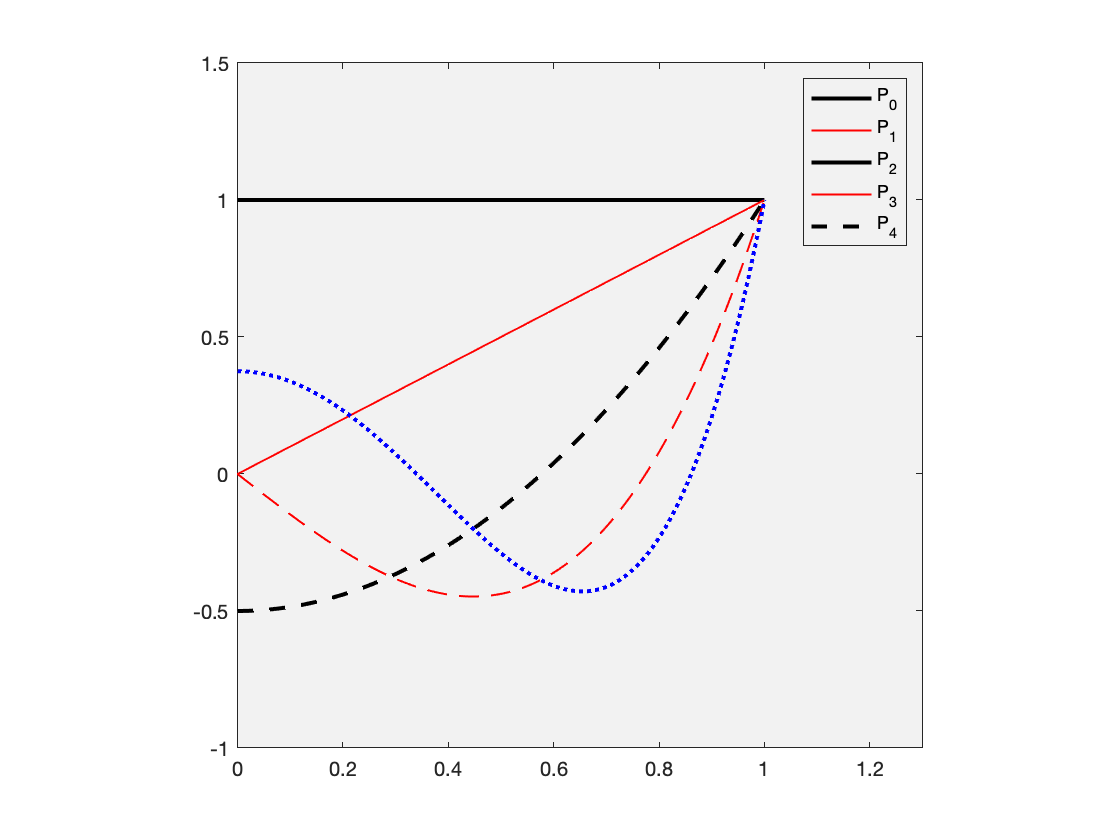

% specify a range of x 
x = 0:0.01:1;

%plot the lengendre polynomial 
plot(x,legendreP(x,0),'k-', 'LineWidth', 2)
hold on
plot(x,legendreP(x,1),'r-', 'LineWidth', 1)
hold on
plot(x,legendreP(x,2),'k--', 'LineWidth', 2)
hold on
plot(x,legendreP(x,3),'r--', 'LineWidth', 1)
hold on
plot(x,legendreP(x,4),'b:', 'LineWidth', 2)
hold off
axis square
ylim([-1,1.5])
set(gca,'Color', [0.95, 0.95, 0.95])
xlim([0,1.3])
legend('P_0','P_1','P_2','P_3','P_4')

#### Recall: different data types

In producing the above plot (and throughout this class), we have used many different *types* of variables. Last week, we saw that we could use `class` to give information about what **kind of information** is stored in a given variable.

class(x)
class('LineWidth')
class(legendreP(x,2))

Last week:

- `myData` is `timetable` class

- `myData.Timestamp` is `datetime` class

- `myData.speed` is `double` class

- `'hello world'` is `char` class

We can also use `whos` to give information, including the data type (or class) of a given variable.

whos x
a = 2;
whos a

In the above, variable a is class *double* requiring a memory of 8 *bytes*.

### Data types (classes) in MATLAB

**Useful MATLAB documentation:**

- [https://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html](https://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html)

#### Bits, bytes, and memory

Remember that computation occurs at the **transistor scale**. Each of the memory locations in a computer is assoicated with multiple transistors and stores a finite sequence of **bi**nary dig**its** (**bits**). 

- Typical storage sizes are **8**, **16**, **32** or** 64 bits**

- A group of **8 bits** is referred to as a **byte**

**Note**: in the above example, `a` is associated with (8x8) **64 bits**.

#### Binary vs. base 10

Each bit may be `off` (**0**) or `on` (**1**). A eight-component line of binary storage can represent a number in base 10. 

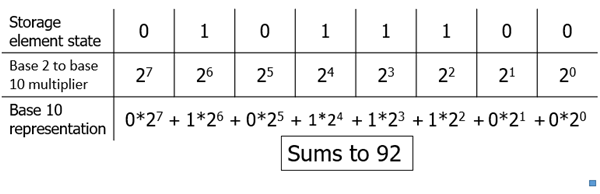

In the line of binary storage, the **position matters** just as in a base 10 number (e.g 9332). In the case of base 2 (binary), each individual digit is either 1 or 0, instead of 0-9 in base 10.

**Note**: the base 10 number is the sum of the binary base (2) raised to the corresponding 0 or 1.

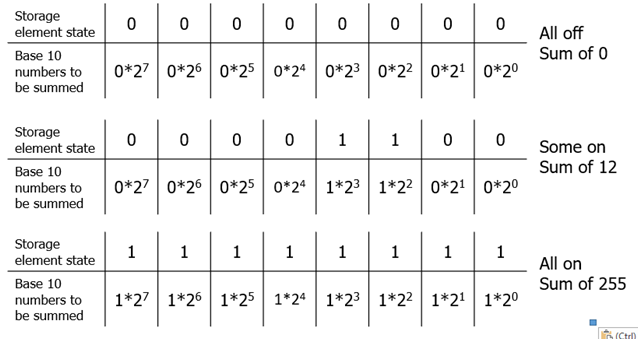

**That is, only **`on`** (1) bits are multiplied by the base 2 multiplier**. The sum of the on (1) bits in base 10 is how our programs interact with memory.

#### Bit size and numbers

Bits enable a computer to represent a "number" using a **digital** infrastructure. **In the section just above, an 8-bit line of storage can be used to store an ****8-bit integer.**

- That is, the integer can take any value between 0 and 2^8 - 1 (255).

In a computer, the bit system limits the** range of values **that can be stored and distinguished. Modern computers operate with **64 bits** while some older architectures and microcontrollers utilize 32 bits.

**Takeaway**: a **larger bit size** yields a larger range of base 10 numbers:

- 8 bit unsigned integers: 0 - 255

- 16 bit unsigned integers: 0 – 65535

- 32 bit unsigned integers: 0 – approx. 4 billion (or $2^{32} -1$)

- 64 bit unsigned integers: 0 – approx. 20 quintillion (or $2^{64} -1$)

In MATLAB, integers may be **signed** or **unsigned**

- **unsigned****: ****only**** positive**

- **signed****: positive ****or**** negative, though the range of potential options is reduced by two.**

**Motivation: **this will be very important when we talk about audio and image processing.

% Convert "numbers" to an integer
a = uint8(4)
b = uint16(20)
c = int32(200)
whos a b c

**Note**: a stored number is clipped (overflow) if numbers larger or smaller than the bit size are stored 

d = uint8(4000)
% Note the range for "signed" integers
f = int8(200)

**Thus**: smaller bit size corresponds to a smaller range of potential integer values

**Unrelated side question: where have we seen integers to be important? Indexing!**

data = [1.5,3,4,2.2];
output = zeros(1,length(data));

% Goal: element-by-element, we want to square each element of data
for k = data
    output(k) = data(k)^2;
    disp(output)
end

#### MATLAB defaults to `double` precision

We often are not interested only in integers but in decimal values. To represent these, MATLAB defaults to the most accurate storage bit length available in the program – **64 bits (aka "**`double`** precision")**. This accuracy **costs storage space** – you can only store so many numbers given your RAM.

- Assignment of bits to representation of a number in 64 bits in accordance with standard [IEEE 754](https://en.wikipedia.org/wiki/IEEE_754)

        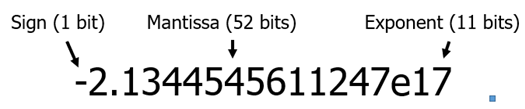

You can query the largest and smallest double precision numbers in MATLAB by invoking `realmax` and `realmin.`

realmax
realmin

**Note**: in the above, "e17" is equivalent to $\times {10}^{17}$

**Note 2****: **double precision can be overridden to economize memory use and (sometimes) computation time

#### Characters arrays and strings

**Character arrays**. We have worked a lot with **character arrays**, which can be read as text/symbols

Just like with number, function handles, and graphic handles, character arrays can be assigned to variables.

a = 'k--';
b = 'LineWidth';
c = 'This is a character array';
disp(c)



**Character arrays are distinguished by single quotes** (`'`).

**Strings**. String arrays are created using double quotes (`"`).

s1 = "This is a string";
disp(s1)


**Similarity**: both can be used to store text information

**Difference**: 

- Each character (including spaces and punctuation) in a character arrays corresponds to an index position in a "vector" or array.

- An entire string corresponds to one index position

% Index the above character array
c(1)
c(5:10)
c(1:2:end)
% Use vector operations to determine the number of characters (including
% spaces) in a piece of text.
length(c)
% Use indexing on string. NOTE: only ONE element of s1
s1(1)

**Thus**: character arrays enable you to retrieve and manipulate each character in a piece of text, while strings treat the entire "block" of text as one unit.

#### Cell arrays

Cell arrays are arrays with indices that can hold a variety of data types or sizes - **all in the same variable**.

**Example**:

C = {'it is Tuesday', [1 5 9], [2 3 1; 5 9 7], ...
    uint8([1 4]), [.5; .1; .9], {'hello',[1 5]}}

In this case, we even place a `cell` in a `cell`.

**Indexing cell arrays**. Cells are indexed much like arrays, except "`()`" **references a cell container** and "`{}`" references the **contents of the cells**

C = {'it is Tuesday', [1 5 9], [2 3 1; 5 9 7], ...
    uint8([1 4]), [.5; .1; .9], {'hello',[1 5]}}
% Reference the cell container
C(1)
class(C(1))
% Reference the contents of a particular cell
C{1}
class(C{1})

**That is:**

- Individual cells can be extracted as full cell units using `()`

- Cell contents can be extracted using `{}`

**Important**: to write to a cell, you must write to the "contents" of a particular cell

**Creating cell arrays**. Cell arrays in productive code are often built within loops and are useful for storing numeric/character arrays of mixed sizes and/or mixed data types

for jj = 1:3
    myCell{jj} = rand(randi(5),randi(5));
end

**Note**: vector and array operations work on cells too:

length(myCell)
size(myCell)
myCell{1}

**Growing cell arrays**. `end + 1` indexing can also be used to grow a cell arrays

tic % initialize timer
 
myCell = cell(0); % create empty cell
 
% Keep filling cell array with random matrices
% until .25 secs have passed
while toc < .01 
    myCell{end+1} = rand(randi(5),randi(5));
end
size(myCell)

**Note**: use `cell(0)` to declare an empty cell array before the loop.

**Shrinking cell arrays**. Cells can be deleted by setting a particular element to `[]`.

for jj = 1:100
    myCell(jj) = [];
end
size(myCell)
myCell{1}

Note: this is different from deleting the contents of individual cells.

for jj = 1:100
    myCell{jj} = [];
end
size(myCell)
myCell{1}

#### Back to the practice problem: making more efficient

%Specify a range of x
x = 0:0.01:1;

%Cell array to store line specifications 
Str = {'k-', 'r-', 'k--', 'r--', 'b:'};

for k = 0:4
    %Plot legrendre polynomial
    plot(x,legendreP(x,k),Str{k+1},'LineWidth',mod(k+1,2)+1)
    hold on
end
hold off


% Graphical parameters
axis square
ylim([-1,1.5])
set(gca,'Color', [0.95, 0.95, 0.95])
xlim([0,1])
legend('P_0','P_1','P_2','P_3','P_4','Location','eastoutside')

**Functions stored at the end of the document.**

**Practice problem: Legendre polynomial**

function pn = legendreP(x,n)
    %calculate the n-th vector legendre polynomial
    %vector 1: vector of positions 
    %vector 2: order of legendre polynomial 
    
    %n = 0 -> pn should be n for all x
    if n == 0 
        %make a vector full of ones based on the size of x 
        pn = ones(size(x));
        
    % if n = 1 -> pn = x    
    elseif n == 1
        pn = x;
        
    %pn depends on previous values 
    else 
        pn = 1/n*((2*n-1)*x.*legendreP(x,n-1) - (n-1)*legendreP(x,n-2));     
    end 
    
end








